# Morphen zweier Bilder 

Verwendung eines Dreiecksnetz anhand gewählte Referenzpunkte, baryzentrischer Koordinaten für die Zielkoordinatenmatrix und einstellbarer Interpolationsart.

## 1. Anleitung

% 1. Referenzpunkte manuell mit dem Skript prepare_data.m erzeugen.
% 
% Folgende Voreinstellungen werden im Abschnitt Einstellungen vorgenommen:
%
% 2. Pfad und Dateinamen von Ursprungs- und Zielbild (Ordner: img_in) sowie 
%    der im Skript prepare_data gewählten Referenzpunkte (Ordner: points) 
%    festlegen. Es können zwei verschiedene Datensätze, bspw. eines für ein
%    triviales Beispiel für Tests eingetragen werden. Das Ergebnis wird als
%    animiertes GIF-Bild im Ordner img_out gespeichert.
%
%    trivial_img   legt fest ob der erste Datensatz mit einem 
%                  voreingestellten trivialen Grauwertbild verwendet werden
%                  soll.
%
% 3. Weitere Optionen einstellen mit true (an) oder false (aus) bzw. String
%    n_frames      legt die Anzahl der Einzelbilder im Ausgangsbild fest.
%    type          (string) legt die Interpolationsart fest. Auswählbar 
%                  sind "bilinear" für bilineare Interpolation und 
%                  "nearest" für die Nächste-Nachbar-Zuordnung.
%    mesh_overlay  legt fest ob das bei der Berechnung verwendete
%                  Dreiecksnetz zu Anschauungszwecken über das berechnete 
%                  Zwischenbild gelegt werden soll.
%    live_plot     legt fest ob das aktuell berechnete Zwischenbild
%                  zur Veranschaulichung angezeigt werden soll. Diese 
%                  Einstellung verlangsamt die Berechnung.
%    final_plot    legt fest, ob ein abschließendes Ergebnis ausgegeben
%                  werden soll. Angezeigt werden Ausgangsbild und
%                  Zielbild mit Dreiecksnetz überlagert, sowie die 
%                  Zwischenbilder bei 25, 50 und 75 % Fortschritt.
%    reps          Für statistische Zwecke: Anzahl an Wiederholungen über 
%                  die die mittlere Berechnungsdauer ermittelt werden soll.
%
% 3. Skript mit "Run" ausführen

close all
clear
clc
addpath('./img_in/')   % Pfad für Eingabebilder
addpath('./img_out')   % Pfad für Ergebnisbild (animiertes GIF)
addpath('./points')    % Pfad für die Referenzpunkte

## 2. Einstellungen

trivial_img = false;   % Wählt 100x100 Pixel Grauwert-Bild für Tests

if trivial_img % Datensatz für triviales Beispielbild
    source_img_file = "T_source_100_20.png";
    target_img_file = "T_target_100_20.png";
    source_points_file = "source_points_trivial_100_20.mat";
    target_points_file = "target_points_trivial_100_20.mat";

else % Datensatz für Gesichter
    source_img_file = "face_01.jpg";
    target_img_file = "face_02.jpg";
    source_points_file = "source_points_face_01_62.mat";
    target_points_file = "target_points_face_02_62.mat";
end

n_frames = 20;  % Anzahl der Einzelbilder
lib_interp2 = false;  % Nutzt die MATLAB-Funktion interp2 statt der eigenen (interpol)
type = "bilinear";  % Interpolationsart: "nearest" oder "bilinear" oder 
                                % weitere Optionen siehe Befehl "doc interp2" falls 
                                % lib_interp2 = true. interp2 schneller.
mesh_overlay = true;  % Dreiecksnetz überlagern (Berechnung langsamer!)
live_plot = true;     % Plot des aktuellen Zwischenbilds für Animation im Skript 
                     % unter Überschrift "4. Morphen" (das GIF-Bild wird auch
                     % ohne diese Option erstellt)
final_plot = true;    % Zusamenfassung nach der Berechnung

reps = 1;  % Anzahl der Wiederholungen (für statistische Zwecke)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 3. Bilder und Punkte laden und prüfen sowie Matrizen vorinitialisieren

timer_values = zeros(reps,1);
for rep = 1:reps  % Um Mittelwert von reps Wiederholungen zu ermitteln 
    disp("Durchgang = " + rep);

% Bilder laden
A = imread(source_img_file);  % Ausgangsbild
B = imread(target_img_file);  % Zielbild

% Gewählte Referenzpunkte laden
load(source_points_file);  % zu Bild A
load(target_points_file);  % zu Bild B

% Punkte in Einzelvektoren zerlegen
xA = source_points(:,1);
yA = source_points(:,2);
xB = target_points(:,1);
yB = target_points(:,2);

n_points = length(xA);

% Größengleichheit beider Bilder verifizieren
[heightA,widthA,channelsA] = size(A);
[heightB,widthB,channelsB] = size(B);

if(heightA~=heightB || widthA~=widthB || channelsA~=channelsB)
    error('Die Bilder haben nicht diesselbe Größe')
end
if(n_points <= 0)
    error('Keine Referenzpunkte angegeben')
end
channels = channelsA; % einheitlicher Name zur besseren Verwendbarkeit
width = widthA;
height = heightA;

% Variablen für Zwischenbilder zur Anzeige
[C_out_25,C_out_50,C_out_75, ...
 VCA_25,VCA_50,VCA_75,VCA_100, ...
 VCB_0,VCB_25,VCB_50,VCB_75] = deal(zeros(size(A))); 

% Eckpunkte der Bilder mit aufnehmen damit alle Pixel beim Morphing
% berücksichtigt werden
xA = [xA;1;width;width;1]; 
yA = [yA;1;1;height;height]; 
xB = [xB;1;width;width;1];
yB = [yB;1;1;height;height];
n_points = n_points + 4;

% Matrizen für Zwischenbild und Interpolation initialisieren
[C,VCA,VCB]= deal(zeros(size(A)));

% Koordinatenebenen für die Suche nach Punkten in Dreiecken
[X,Y] = meshgrid(1:width,1:height);

alpha = 0; % Gewichtungs-/Überblendungsfaktor

% Dateiname für Ausgabe
out_fname = "output_" + n_points + "p_" + n_frames + "f_" + type;

Durchgang = 1


## 4. Morphen und Ausgabe als GIF-Datei

disp("Starte Morphing: " + n_points + " Punkte u. " + n_frames + " Frames")

Starte Morphing: 66 Punkte u. 20 Frames


Frame: 1   Alpha: 0.05
Frame: 2   Alpha: 0.1
Frame: 3   Alpha: 0.15
Frame: 4   Alpha: 0.2
Frame: 5   Alpha: 0.25
Frame: 6   Alpha: 0.3
Frame: 7   Alpha: 0.35
Frame: 8   Alpha: 0.4
Frame: 9   Alpha: 0.45
Frame: 10   Alpha: 0.5
Frame: 11   Alpha: 0.55
Frame: 12   Alpha: 0.6
Frame: 13   Alpha: 0.65
Frame: 14   Alpha: 0.7
Frame: 15   Alpha: 0.75
Frame: 16   Alpha: 0.8
Frame: 17   Alpha: 0.85
Frame: 18   Alpha: 0.9
Frame: 19   Alpha: 0.95


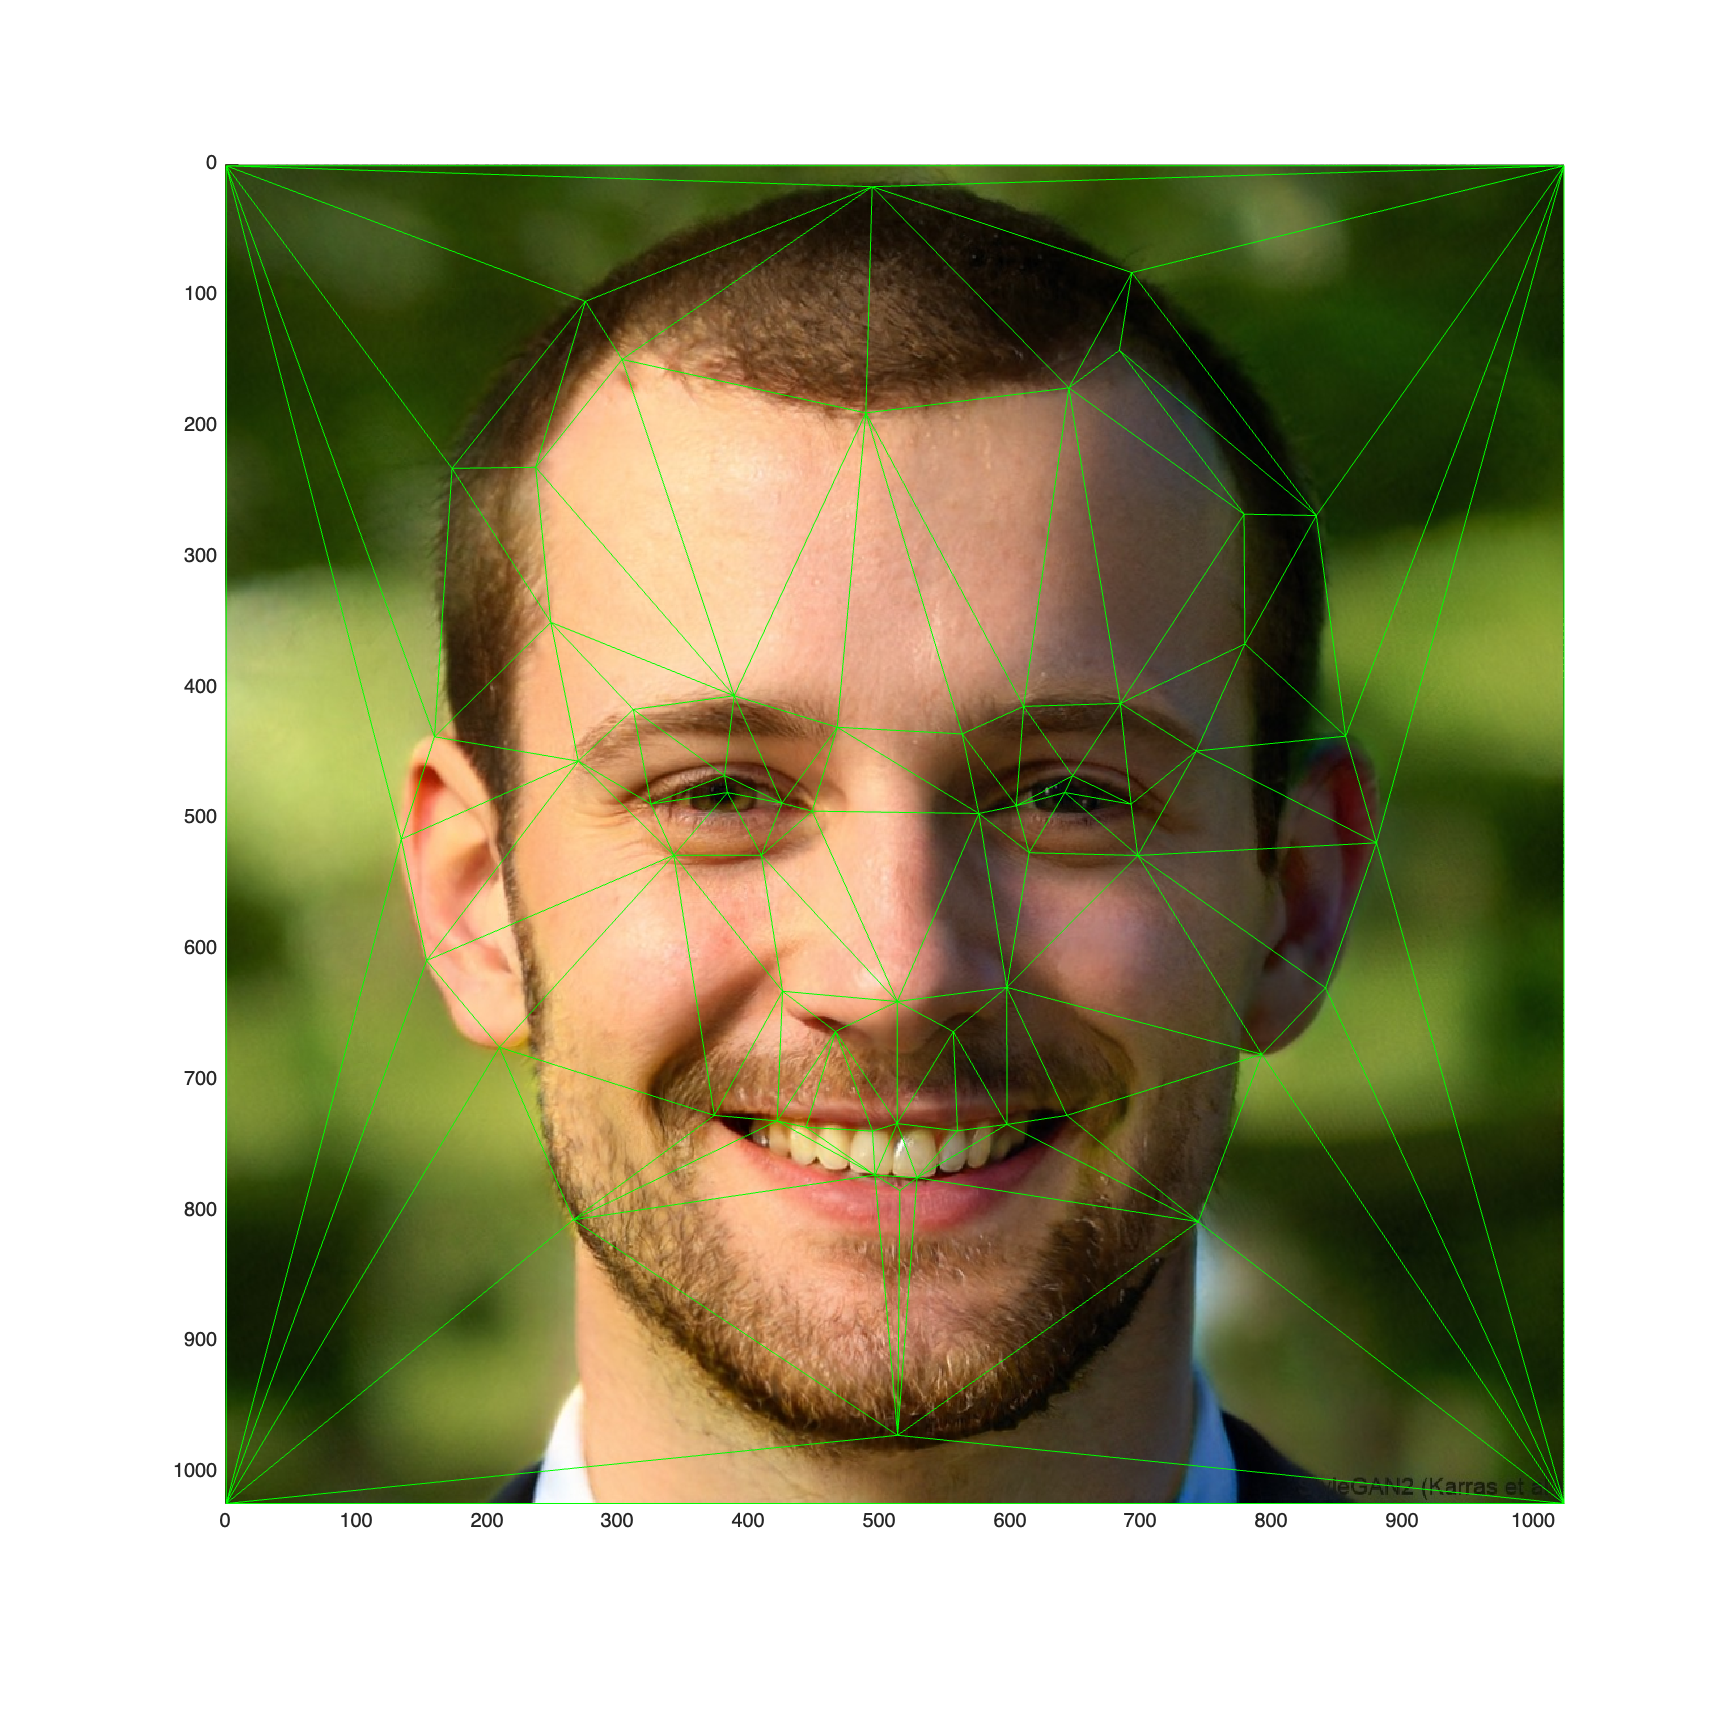

Frame: 20   Alpha: 1


morph_timer = tic; % Timer für Berechnung und GIF-Erstellung starten

for i = 1:n_frames
  
    % Bilden der Referenzpunkte des Zwischenbilds C mit steigender
    % Gewichtung der Referenzpunktkoordinaten von Bild B mittels alpha
    xC = (1 - alpha) * xA + alpha * xB;  
    yC = (1 - alpha) * yA + alpha * yB; 

    % Delaunay Triangulierung: Verbinden der Referenzpunkte des aktuellen 
    % Zwischenbildes zu einem Dreiecksnetz.
    triC = delaunay(xC,yC); % Nummern zusammengehörender Referenzpunkte
    ntri = size(triC,1);    % Anzahl der Dreiecke

    % Definieren aller der Punkte, die jeweils in einem Dreieck liegen und
    % berechnen der Koordinatenzeigermatrizen für die nachfolgende 
    % Interpolation aus der Gesamtmenge der Dreiecke.
    [xCA,yCA,xCB,yCB] = deal(zeros(height,width)); % neu auf Null setzen
    for k = 1:ntri
        % Baryzentrische Koordinaten des Dreiecks berechnen
	    [w1,w2,w3] = barycentric(X,Y,xC(triC(k,1)),yC(triC(k,1)), ...
            xC(triC(k,2)),yC(triC(k,2)),xC(triC(k,3)),yC(triC(k,3)));
        % Koordinatenzeigermatrizen berechnen
	    xCA = xCA + w1.*xA(triC(k,1))+w2.*xA(triC(k,2))+w3.*xA(triC(k,3));
	    yCA = yCA + w1.*yA(triC(k,1))+w2.*yA(triC(k,2))+w3.*yA(triC(k,3));
	    xCB = xCB + w1.*xB(triC(k,1))+w2.*xB(triC(k,2))+w3.*xB(triC(k,3));
	    yCB = yCB + w1.*yB(triC(k,1))+w2.*yB(triC(k,2))+w3.*yB(triC(k,3));
    end
    
    % Verzerren von A und B Bild durch Interpolation auf die 
    % Zielkoordinaten 
    for c = 1:min(channels, 3)
        if lib_interp2
            VCA(:,:,c) = interp2(double(A(:,:,c)),xCA,yCA,type);
            VCB(:,:,c) = interp2(double(B(:,:,c)),xCB,yCB,type);
        else
            VCA(:,:,c)=interpol(width,height,double(A(:,:,c)),xCA,yCA,type);
            VCB(:,:,c)=interpol(width,height,double(B(:,:,c)),xCB,yCB,type);
        end
    end

    % Berechnen des Zwischenbilds C durch Überblenden (cross-dissolve) der 
    % verzerrten Bilder VCA und VCB
    C = alpha * VCB + (1 - alpha) * VCA;

    % Optional: Bild zur späteren Darstellung mit Dreiecksnetz und 
    % Koordinatensystem überlagern
    if mesh_overlay
        if channels == 1
            C_out=overlay_triplot(C,width,height,triC,xC,yC,live_plot);
            colormap(gray(255)) % sonst erscheint das Bild gelb und blau
            VCA_out=overlay_triplot(VCA,width,height,triC,xC,yC,live_plot);
            colormap(gray(255)) % sonst erscheint das Bild gelb und blau
            VCB_out=overlay_triplot(VCB,width,height,triC,xC,yC,live_plot);
            colormap(gray(255)) % sonst erscheint das Bild gelb und blau
            set(gcf,'Visible','on')
        end
        C_out = overlay_triplot(C,width,height,triC,xC,yC,live_plot);
        VCA_out=overlay_triplot(VCA,width,height,triC,xC,yC,live_plot);
        VCB_out=overlay_triplot(VCB,width,height,triC,xC,yC,live_plot);
    else
        C_out = uint8(C);
        VCA_out = uint8(VCA);
        VCB_out = uint8(VCB);
        if live_plot 
            imshow(C_out)
        end
    end
    
    if final_plot
        % Zwischenbilder C, VCA und VCB in 25%-Schritten zur 
        % Veranschaulichung
        if i == 1
            C_out_0 = C_out;
            VCA_0 = VCA_out;
            VCB_0 = VCB_out;
        elseif(i == round(n_frames/4))
            C_out_25 = C_out;
            VCA_25 = VCA_out;
            VCB_25 = VCB_out;
        elseif(i == round(n_frames/2))
            C_out_50 = C_out;
            VCA_50 = VCA_out;
            VCB_50 = VCB_out;
        elseif(i == round(3*n_frames/4))
            C_out_75 = C_out;
            VCA_75 = VCA_out;
            VCB_75 = VCB_out;
        elseif(i == n_frames)
            C_out_100 = C_out;
            VCA_100 = VCA_out;
            VCB_100 = VCB_out;
        end
    end

    % GIF-Datei erzeugen bzw. aktuelles Zwischenbild anhängen
    if size(C_out,3) == 3
        [imind,cm] = rgb2ind(C_out,256); 
    else
        [imind,cm] = gray2ind(C_out,256); 
    end
    if i == 1 
      imwrite(imind,cm,sprintf("img_out/%s.gif",out_fname),'gif',...
          'Loopcount',inf,'DelayTime',0); 
    else 
      imwrite(imind,cm,sprintf("img_out/%s.gif",out_fname),'gif',...
          'WriteMode','append','DelayTime',0); 
    end
    
    % alpha-Faktor erhöhen
    alpha = alpha + 1/n_frames;

    % Fortschrittsanzeige: Aktuelle Framenummer und alpha-Faktor ausgeben
    disp("Frame: " + i + "   Alpha: " + alpha);

end % for n_frames

timer_values(rep) = toc(morph_timer); % Timer für Berechnung stoppen

end % for reps
timer_avg = mean(timer_values);
disp("Mittlere Rechenzeit "+reps+" Wdh. = "+timer_avg+" s");

Mittlere Rechenzeit 1 Wdh. = 54.0718 s


## 5. Ergebnisplots 

(GIF-Datei siehe Ordner img_out)

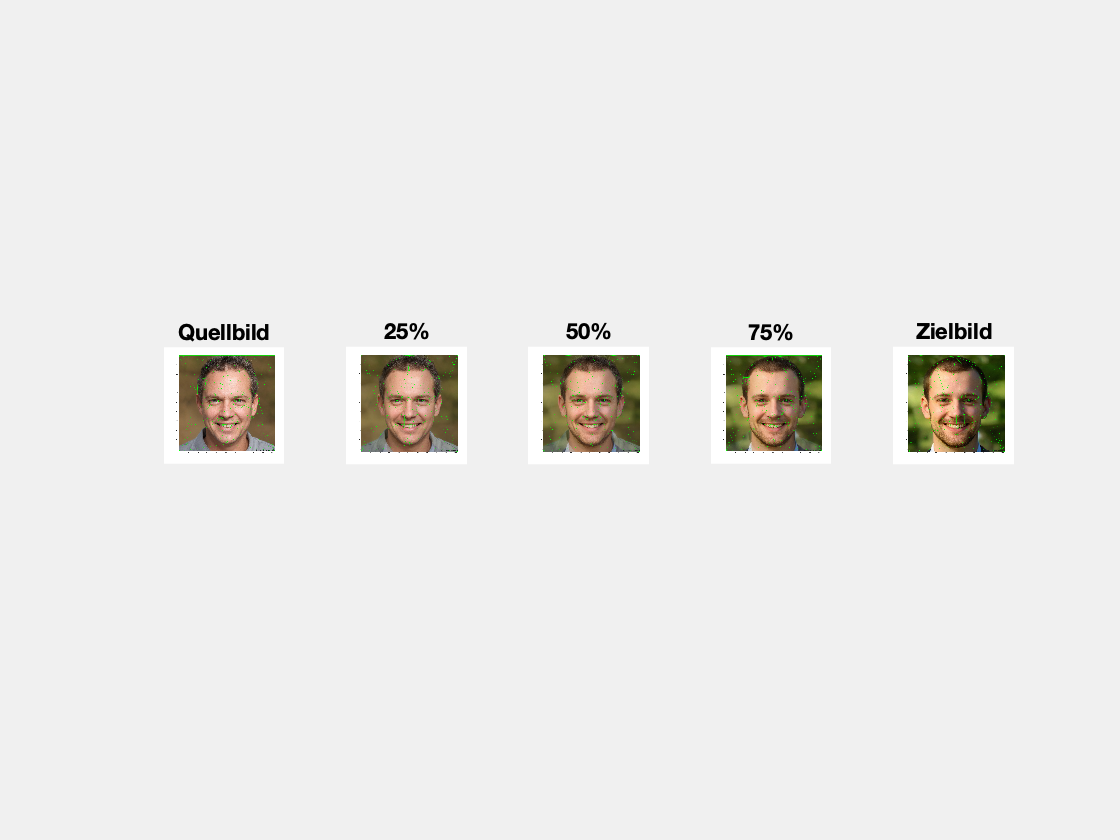

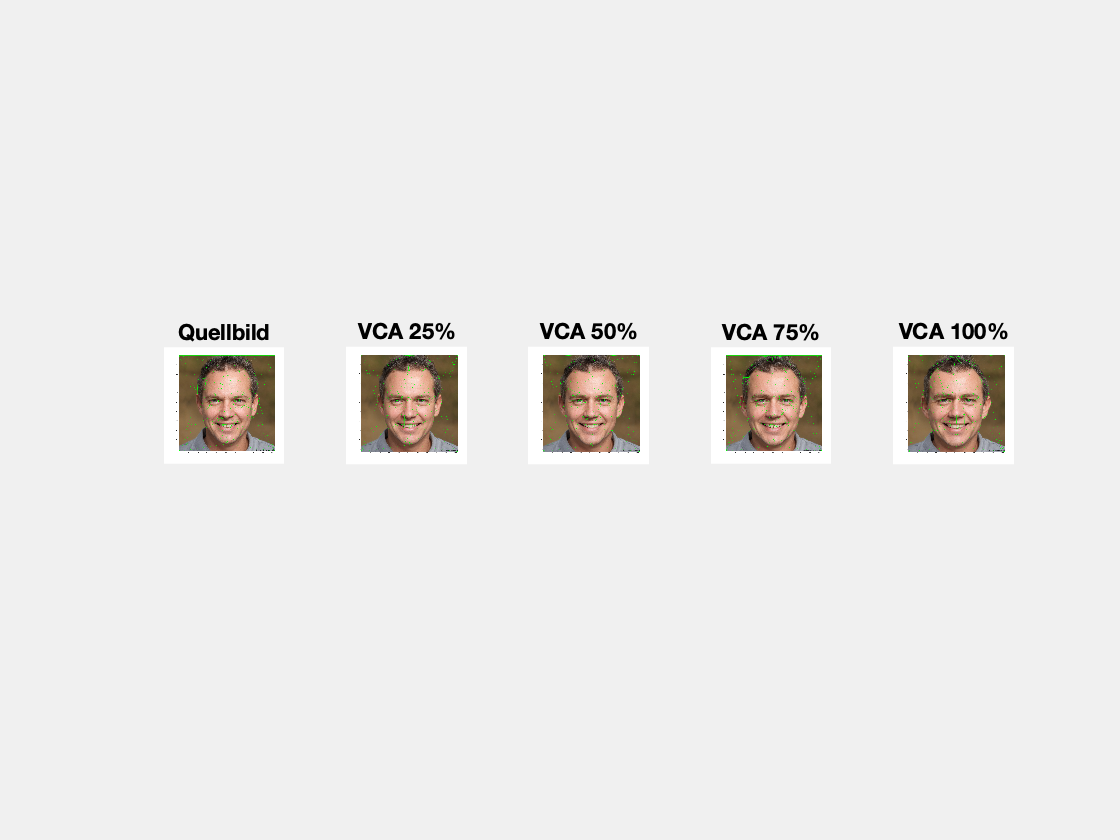

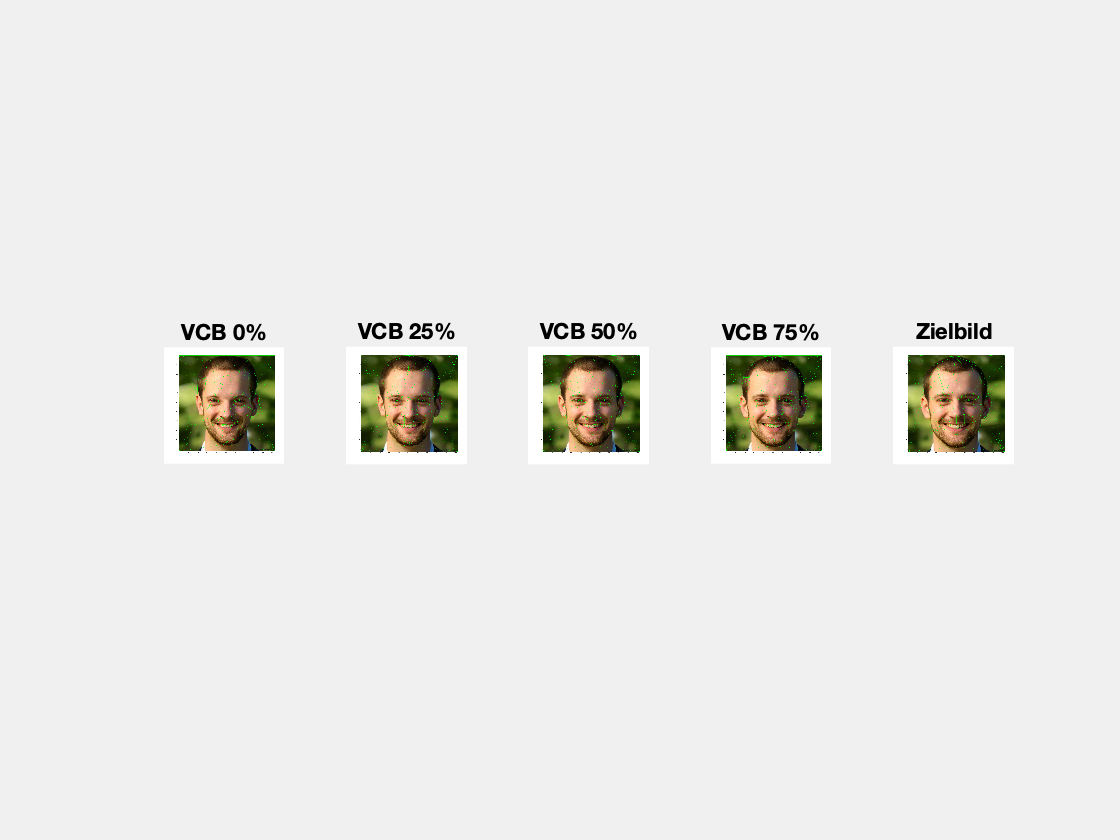

if final_plot
    
    figure(); % Zwischenbilder C bei 0, 25, 50, 75 und 100 % darstellen
    subplot(1,5,1);
    imshow(C_out_0);
    title("Quellbild");
    subplot(1,5,2);
    imshow(C_out_25);
    title("25%");
    subplot(1,5,3);
    imshow(C_out_50);
    title("50%");
    subplot(1,5,4);
    imshow(C_out_75);
    title("75%");
    subplot(1,5,5);
    imshow(C_out_100);
    title("Zielbild");

    figure(); % VCA bei 0, 25, 50, 75 und 100 % darstellen
    subplot(1,5,1);
    imshow(VCA_0);
    title("Quellbild");
    subplot(1,5,2);
    imshow(VCA_25);
    title("VCA 25%");
    subplot(1,5,3);
    imshow(VCA_50);
    title("VCA 50%");
    subplot(1,5,4);
    imshow(VCA_75);
    title("VCA 75%");
    subplot(1,5,5);
    imshow(VCA_100);
    title("VCA 100%");

    figure(); % VCB bei 0, 25, 50, 75 und 100 % darstellen
    subplot(1,5,1);
    imshow(VCB_0);
    title("VCB 0%");
    subplot(1,5,2);
    imshow(VCB_25);
    title("VCB 25%");
    subplot(1,5,3);
    imshow(VCB_50);
    title("VCB 50%");
    subplot(1,5,4);
    imshow(VCB_75);
    title("VCB 75%");
    subplot(1,5,5);
    imshow(VCB_100);
    title("Zielbild");

end